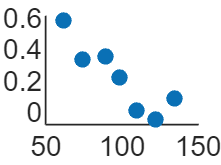


close all;
clear all;

save_data = 0;
maindir = '\\Artemis-pc\Data\2026-09-15\';

xc = 114.6;
dx1 = [47.77 34.97 20.45 ...
    10.79 0 -12.70 -25.14];
dx = xc-(dx1+50.28-);

dB = [0.58 0.33 0.35 ...
    0.21 0 -0.06 0.08];
errB = [3 2 3 ...
    4 4 3 2]*1e-2;
wB = 1./errB.^2;

f1 = figure; hold on;
errorbar(dx,dB,errB,'.','CapSize',0,...
    'MarkerSize',14,'LineWidth',1.5,...
    'Color',[0.04,0.44,0.71]);

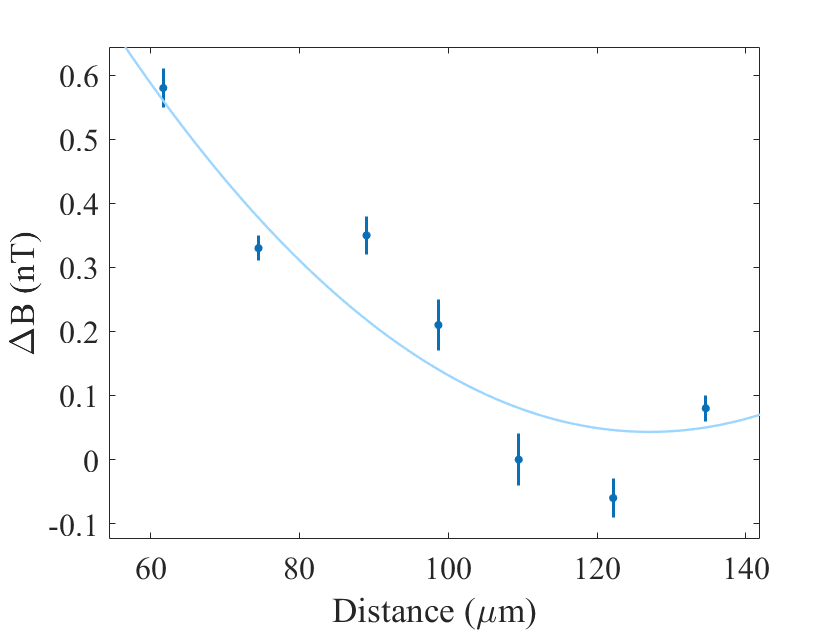


margin_per = 0.1;

xmin = min(dx)-margin_per*(max(dx)-min(dx));
xmax = max(dx)+margin_per*(max(dx)-min(dx));

ymin = min(dB)-margin_per*(max(dB)-min(dB));
ymax = max(dB)+margin_per*(max(dB)-min(dB));

xlim([xmin xmax]);
ylim([ymin ymax]);

set(gcf,'Visible','on');

%% 拟合: '无标题拟合 1'。
[xData, yData, weights] = prepareCurveData( dx, dB, wB );

% 设置 fittype 和选项。
ft = fittype( 'F*(x-x0)^2+b0', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0 1e-4 120];
opts.Weights = weights;

% 对数据进行模型拟合。
[fitted, gof] = fit( xData, yData, ft, opts );
interval = confint(fitted);
F = fitted.F;
F_err = abs(interval(1,2)-interval(2,2))/4;
F_upper = abs(F)+1*F_err;
b0 = fitted.b0;
b0_err = abs(interval(1,1)-interval(2,1))/4;
z0 = fitted.x0;
z0_err = abs(interval(1,3)-interval(2,3))/4;

% 绘制数据拟合图。
l = plot(fitted);
l.LineWidth = 1.2;
l.Color = [0.61 0.84 1];

legend off;

set(gca,'FontName','times new roman',...
    'FontSize',16);
xlabel('Distance (\mum)');
ylabel('\DeltaB (nT)');
box on;


a171 = 6.08;   % um
b171 = 10.97;
a173 = 5.96;
b173 = 11.99;

znear = 65;   % um
zfar = 100;

step = 1e-4;
range = 4;
z171 = [-range:step:range]*a171;
z173 = [-range:step:range]*a173;

% % B = F/(z-z0)+Boff %
% F = 1.18e3;   % nT*um
% %Boff = -0.94;   % nT
% z0 = -100;   % um

% B = F*(z-z0)^2+Boff %



% near %
Bn171 = 0;
Bn173 = 0;
n171 = 0;
n173 = 0;
for k = 1:length(z171)
    %Bz171 = F/(znear+z171(k)-z0);
    Bz171 = F_upper*(znear+z171(k)-z0)^2;
    dn171 = exp(-(z171(k))^2/a171^2);
    temp = Bz171*dn171;
    Bn171 = Bn171 + temp;
    n171 = n171+dn171;

    %Bz173 = F/(znear+z173(k)-z0);
    Bz173 = F_upper*(znear+z173(k)-z0)^2;
    dn173 = exp(-(z173(k))^2/a173^2);
    temp = Bz173*dn173;
    Bn173 = Bn173 + temp;
    n173 = n173+dn173;
end

Bn171 = Bn171/n171;
Bn173 = Bn173/n173;

% far %
Bf171 = 0;
Bf173 = 0;
n171 = 0;
n173 = 0;
for k = 1:length(z171)
    %Bz171 = F/(zfar+z171(k)-z0);
    Bz171 = F_upper*(zfar+z171(k)-z0)^2;
    dn171 = exp(-(z171(k))^2/a171^2);
    temp = Bz171*dn171;
    Bf171 = Bf171 + temp;
    n171 = n171+dn171;

    %Bz173 = F/(zfar+z173(k)-z0);
    Bz173 = F_upper*(zfar+z173(k)-z0)^2;
    dn173 = exp(-(z173(k))^2/a173^2);
    temp = Bz173*dn173;
    Bf173 = Bf173 + temp;
    n173 = n173+dn173;
end

Bf171 = Bf171/n171;
Bf173 = Bf173/n173;



B0 = 1e4;   % nT
gamma171 = 7.50*1e3;   % freq, uHz/nT
gamma173 = 2.07*1e3*5;

Rn = (Bn171+B0*1.4)/(Bn173+B0*1.4)* ...
    gamma171/gamma173;
Rf = (Bf171+B0*1.4)/(Bf173+B0*1.4)* ...
    gamma171/gamma173;
%dR = Rn-Rf
%df_R = dR*123*1e6*1.4   % uHz

dBn = Bn171-Bn173   % nT

dBn = 0.0502

dBf = Bf171-Bf173   % nT

dBf = 0.0502

df_B = (dBn)*gamma171   % uHz

df_B = 376.4265


if save_data == 1
    savefig(f1,[maindir,'B_2nd.fig']);
    saveas(f1,[maindir,'B_2nd.png']);

    save([maindir,'B_2nd.mat']);
end